# Project Script - BMES 543

Jiaqi Xiang, Xuanjie(Gavin) Gao

clear;clc;close all

## Download data - GSE 13425

% GSE13425
% Download GSE data
GSE1 = bmes_downloadandparsegse_cached('GSE13425'); % Dataset for training.

Reading C:/Users/GavinGao/AppData/Local/Temp/GSE13425.txt ...


% Store GSE data to variable gsedata
gsedata1 = GSE1.Data;
% Obtain GPL platform id
GPLid1 = GSE1.Header.Series.platform_id;
% Download GPL data
GPL1 = bmes_downloadandparsegpl(GPLid1);

## Download data - GSE 13351

% GSE13351
% Download GSE data
GSE2 = bmes_downloadandparsegse_cached('GSE13351');

Reading C:/Users/GavinGao/AppData/Local/Temp/GSE13351.txt ...


% Store GSE data to variable gsedata
gsedata2 = GSE2.Data;
% Obtain GPL platform id
GPLid2 = GSE2.Header.Series.platform_id;
% Download GPL data
GPL2 = bmes_downloadandparsegpl(GPLid2);

## Convert probes into corresponded gene symbol - GSE 13425

Store ID into variable GPLProbes

GPLProbes1 = GPL1.Data(:,strcmp(GPL1.ColumnNames,'ID'));
% Obtain gene symbol from gpl data and store them into variable GPLGenes
GPLGenes1 = GPL1.Data(:,strcmp(GPL1.ColumnNames,'Gene Symbol'));
% Obtain row names in gse data
GSEProbes1 = gsedata1.rownames;
MAP_GSE_GPL_1 = zeros(numel(GSEProbes1),1);

% The following step is to match gse probes with gpl probes, then to obtain
% corresponded gene symbol
map1 = containers.Map(GPLProbes1,1:numel(GPLProbes1));
% Create "address book"
for i=1:numel(GSEProbes1)
if map1.isKey(GSEProbes1{i})
   MAP_GSE_GPL_1(i)=map1(GSEProbes1{i}); 
end
end

GSEGenes1(find(MAP_GSE_GPL_1)) = GPLGenes1(MAP_GSE_GPL_1(find(MAP_GSE_GPL_1)));

gsedata1 = gsedata1.rownames(':',GSEGenes1);

% Normalization
% Normalize data
gsedata1norm = double(gsedata1);
gsedata1norm = bsxfun(@minus,gsedata1norm,mean(gsedata1norm));
gsedata1norm = bsxfun(@rdivide,gsedata1norm,std(gsedata1norm));
% See detailed comments above
% If with problem, change back to gsedata2new
gsedata1 = bioma.data.DataMatrix(gsedata1norm,gsedata1.RowNames,gsedata1.ColNames);

## Convert probes into corresponded gene symbol - GSE 13351

GPLProbes2 = GPL2.Data(:,strcmp(GPL2.ColumnNames,'ID'));
% Obtain gene symbol from gpl data and store them into variable GPLGenes
GPLGenes2 = GPL2.Data(:,strcmp(GPL2.ColumnNames,'Gene Symbol'));
% Obtain row names in gse data
GSEProbes2 = gsedata2.rownames;
MAP_GSE_GPL_2 = zeros(numel(GSEProbes2),1);

% The following step is to match gse probes with gpl probes, then to obtain
% corresponded gene symbol
map2 = containers.Map(GPLProbes2,1:numel(GPLProbes2));
% Create "address book"
for i=1:numel(GSEProbes2)
if map2.isKey(GSEProbes2{i})
   MAP_GSE_GPL_2(i)=map2(GSEProbes2{i}); 
end
end

GSEGenes2(find(MAP_GSE_GPL_2)) = GPLGenes2(MAP_GSE_GPL_2(find(MAP_GSE_GPL_2)));

gsedata2 = gsedata2.rownames(':',GSEGenes2);
% Normalize data
gsedata2norm = double(gsedata2);
gsedata2norm = bsxfun(@minus,gsedata2norm,mean(gsedata2norm));
gsedata2norm = bsxfun(@rdivide,gsedata2norm,std(gsedata2norm));
% See detailed comments above
% If with problem, change back to gsedata2new
gsedata2 = bioma.data.DataMatrix(gsedata2norm,gsedata2.RowNames,gsedata2.ColNames);

## Convert column names - GSE 13425

groupnames1 = {'T_ALL' 'B_ALL'};
colname1 = gsedata1.ColNames;
colname1(1:36)=groupnames1(1); % 1-36 T ALL samples, 37-end B ALL samples in GSE 13425.
colname1(37:end)=groupnames1(2); 
gsedata1 = set(gsedata1,'ColNames',colname1);

Data1_TALL = strcmp(colname1,'T_ALL');
Data1_BALL = strcmp(colname1,'B_ALL');


## Convert column names - GSE 13351

groupnames2 = {'T_ALL' 'B_ALL'};
colname2 = gsedata2.ColNames;
colname2(1:15)=groupnames2(1); % 1-15 T ALL samples, 16-end B ALL samples in GSE 13425, 
%from GSE2.Header.Samples.characteristics_chi1(2,:).
colname2(16:end)=groupnames2(2); 
gsedata2 = set(gsedata2,'ColNames',colname2);

Data2_TALL = strcmp(colname2,'T_ALL');
Data2_BALL = strcmp(colname2,'B_ALL');


## t test and display p-Values - GSE 13425

% T test
[~,gsepv1] = ttest2(gsedata1(:,Data1_TALL)',gsedata1(:,Data1_BALL)','Vartype','unequal');
% Flip data for demonstration
gsepv1_flip = gsepv1';
% Generate table for sorting
gsepv1table = table(gsedata1.RowNames,gsepv1_flip );
% Set variablename for table
gsepv1table.Properties.VariableNames = ["Gene","p-values"];
% Sort by p-values
pvalssort_1 = sortrows(gsepv1table,'p-values');
disp(pvalssort_1(1:10,:))

       Gene         p-values 
    ___________    __________

    {'CD3D'   }    1.4771e-76
    {'CD3G'   }    3.9372e-60
    {'NPY'    }     6.632e-46
    {'TRBC1'  }    5.5488e-45
    {'STK32B' }    1.2746e-44
    {'HLA-DMB'}     1.277e-44
    {'ARL4C'  }    6.3733e-44
    {'ARL4C'  }    8.0693e-40
    {'TCL1A'  }    1.7662e-39
    {'GATA3'  }    1.8554e-39



## Calculate fold change - GSE 13425

% Calculate fold change
fc_1 = mean(gsedata1(:,Data1_TALL),2) ./ mean(gsedata1(:,Data1_BALL),2) ;
% Create table
gsecmp1 = table(gsedata1.RowNames,gsepv1_flip,fc_1);
% Change table variable names
gsecmp1.Properties.VariableNames = ["Gene","pValues","Foldchange"];
% Create filter, only need gene with p values smaller than 0.01 and fold
% change greter than 5
gsecmp1_filter = gsecmp1.pValues<=0.05&abs(gsecmp1.Foldchange)>5;
% Apply filter
gsecmp1_final = gsecmp1(gsecmp1_filter,:);
% Sort by p values
fcsort_1 = sortrows(gsecmp1_final,'pValues');
% Checker
disp(fcsort_1(1:10,:))

      Gene        pValues      Foldchange
    _________    __________    __________

    {'CD3D' }    1.4771e-76      19.374  
    {'TRBC1'}    5.5488e-45      56.486  
    {'CD247'}    2.1184e-38      -65.19  
    {'LCK'  }    3.8963e-35      29.438  
    {'LCK'  }    1.3175e-34     -9.2388  
    {'ZAP70'}    1.2152e-30      5.5145  
    {'SMAD3'}    2.6322e-30     -5.4464  
    {'CD3E' }    9.6603e-28      6.9273  
    {'MPPE1'}    1.0185e-26      -10.95  
    {'LAT'  }    1.2041e-24     -7.9319  



Error using classreg.learning.FullClassificationRegressionModel.prepareDataCR (line 234)
X and Y do not have the same number of observations.

Error in ClassificationSVM.prepareData (line 641)
                classreg.learning

## Clustergram

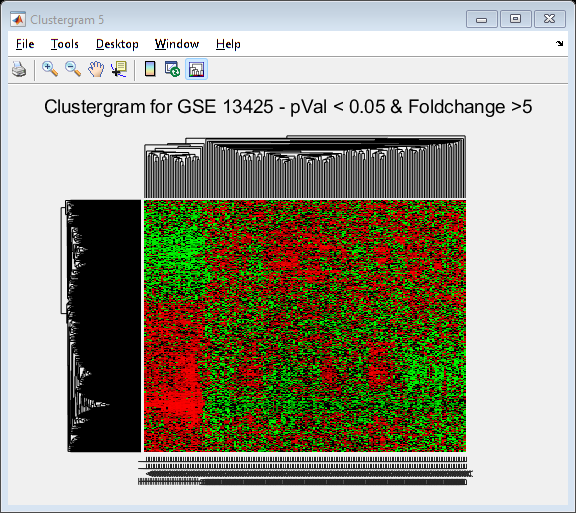

% Combine p values and fold change
pvfc1 = [gsepv1_flip fc_1];
% Create new data matrix for filtering
clustermatrix1 = bioma.data.DataMatrix(pvfc1,gsedata1.RowNames,["pVal","FC"]);
% Filter genes with p values greater than 0.05 and have abs foldchange
% greater than 5
Isig=clustermatrix1(:,'pVal')<=0.05&abs(clustermatrix1(:,'FC'))>5; 
% Get data
gsedataIsig = gsedata1(Isig,:);
% Plot clustergram
cluster1 = clustergram(gsedataIsig,'Standardize','Row');
set(cluster1,'ColumnLabelsRotate',90)
addTitle(cluster1,'Clustergram for GSE 13425 - pVal < 0.05 & Foldchange >5')

## t test and display p-Values - GSE 13351

% Normalize data
gsedata2norm = double(gsedata2);
gsedata2norm = bsxfun(@minus,gsedata2norm,mean(gsedata2norm));
gsedata2norm = bsxfun(@rdivide,gsedata2norm,std(gsedata2norm));
% Convert normalized data back to DataMatrix
gsedata2 = bioma.data.DataMatrix(gsedata2norm,gsedata2.RowNames,gsedata2.ColNames);
% T-Test on GSE 13351
[~,gsepv2] = ttest2(gsedata2(:,Data2_TALL)',gsedata2(:,Data2_BALL)','Vartype','unequal');
% Flip values for demonstration
gsepv2_flip = gsepv2';
% Create table for sorting
gsepv2table = table(gsedata2.RowNames,gsepv2_flip);
% Grant column names
gsepv2table.Properties.VariableNames = ["Gene","p-values"];
% Sort by p-values
pvalssort_2 = sortrows(gsepv2table,'p-values');
disp(pvalssort_2(1:10,:))

       Gene         p-values 
    ___________    __________

    {'CD3D'   }    1.3029e-41
    {'TCF7'   }    5.8166e-38
    {'NAV1'   }    2.2144e-34
    {'RAB17'  }    1.0292e-33
    {'TRBC1'  }    9.0371e-33
    {'PGPEP1' }    4.1668e-31
    {'CEP85L' }    3.0416e-30
    {'C1QTNF4'}     3.725e-29
    {'NGFRAP1'}    4.1433e-27
    {'BMP2'   }    7.1253e-27



## Calculate fold change - GSE 13351

% Calculate fold change
fc_2 = mean(gsedata2(:,Data2_TALL),2) ./ mean(gsedata2(:,Data2_BALL),2) ;
% Create table
gsecmp2 = table(gsedata2.RowNames,gsepv2_flip,fc_2);
% Change table variable names
gsecmp2.Properties.VariableNames = ["Gene","pValues","Foldchange"];
% Create filter, only need gene with p values smaller than 0.01 and fold
% change greter than 5
gsecmp2_filter = gsecmp2.pValues<=0.05&abs(gsecmp2.Foldchange)>5;
% Apply filter
gsecmp2_final = gsecmp2(gsecmp2_filter,:);
% Sort by p values
fcsort_2 = sortrows(gsecmp2_final,'pValues');
% Checker
disp(fcsort_2(1:10,:))

       Gene         pValues      Foldchange
    ___________    __________    __________

    {'CD3D'   }    1.3029e-41       5.101  
    {'RAB17'  }    1.0292e-33     -8.3237  
    {'NGFRAP1'}    4.1433e-27      8.7362  
    {'CD9'    }    3.9889e-26      -12.25  
    {'BIN2'   }    3.5818e-24      -46.21  
    {'CAMK4'  }    5.4246e-24     -7.3856  
    {'CD3E'   }    1.8277e-20      9.2405  
    {'TMIGD2' }    3.6795e-20      10.577  
    {'CAMK4'  }    3.7482e-20     -73.237  
    {'FFAR1'  }    8.6905e-20     -11.801  



## Clustergram

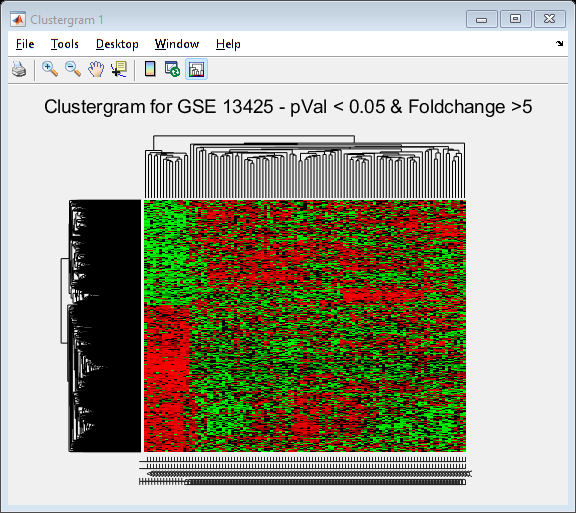

% See comments in Clustergram section above
pvfc2 = [gsepv2_flip fc_2];
clustermatrix2 = bioma.data.DataMatrix(pvfc2,gsedata2.RowNames,["pVal","FC"]);
Isig2=clustermatrix2(:,'pVal')<=0.05&abs(clustermatrix2(:,'FC'))>5; 
gsedataIsig2 = gsedata2(Isig2,:);
cluster2 = clustergram(gsedataIsig2,'Standardize','Row');
set(cluster2,'ColumnLabelsRotate',90)
addTitle(cluster2,'Clustergram for GSE 13425 - pVal < 0.05 & Foldchange >5')

## Gene checker

find(strcmp(gsecmp1_final.Gene(:),'NOTCH1')==1)


ans =

  0×1 empty double column vector



find(strcmp(gsecmp2_final.Gene(:),'NOTCH1')==1)


ans =

  0×1 empty double column vector



## Find intersections

% Find intersections between 2 data set
[Gene_int,GSE1_index,GSE2_index] = intersect(gsedata1.RowNames,gsedata2.RowNames);
% Update data set 1 with intersected gene only
gsedata1_intersect = gsedata1((GSE1_index(2:end)),:);
% Update data set 2 with intersected gene only
gsedata2_intersect = gsedata2((GSE2_index(2:end)),:);
% Combine 2 data sets for t-test and fold change
gsedata3 = [gsedata1_intersect(:,1:36) gsedata2_intersect(:,1:15) gsedata1_intersect(:,37:190) gsedata2_intersect(:,16:107)];
